# Limitations of Neuron Coverage

Several studies investigate the relationship between coverage and various definitions of robustness for deep learning networks. Many of these studies find little to no evidence that increasing neuron coverage improves network robustness [1] - [5]. 

This example illustrates one limitation of neuron coverage. A network that is over parameterized can have two different sets of learnable parameters that produce functionally equivalent networks. Although the predictions from these two networks are identical, they can have different neuron coverage.

In this example:

- Train a neural network to describe the function $f\left(x\right)=x+1$. 

- Find a functionally equivalent network with different learnable weights.

- Demonstrate that the neuron coverage is different for the two networks.

## Generate Data

Simulate data using the true function with some Gaussian noise added to the responses.

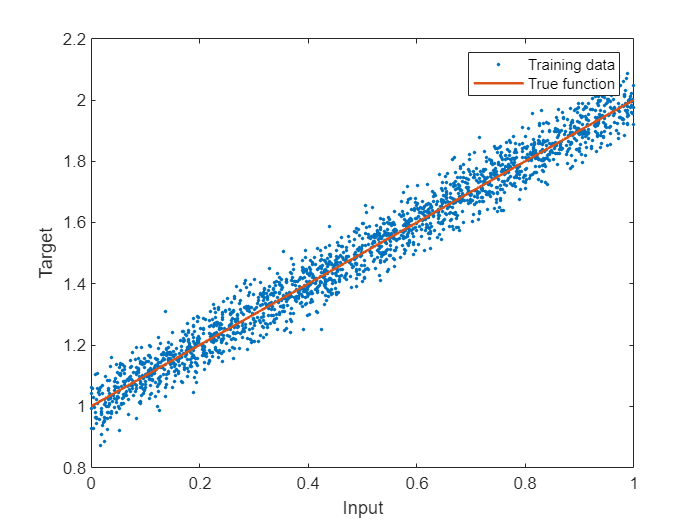

rng("default")
numTrainObservations = 2000;
XTrain = rand(numTrainObservations,1);
TTrain = XTrain(:,1) + 1 + 0.05*randn(numTrainObservations,1);

figure
plot(XTrain,TTrain,'.');
hold on
plot(XTrain,XTrain+1,LineWidth=1.5)
hold off
xlabel("Input");
ylabel("Target")
legend("Training data","True function");

## Define Network

Define the network. The first layer is a `featureInputLayer` with input size 1 representing the scalar input. Next, add two fully connected layers with size 3 and 1, respectively. The final layer is a regression layer. 

numInputs = 1;
numOutputs = 1;
sizeFC1 = 3;

layers = [featureInputLayer(numInputs), ...
    fullyConnectedLayer(sizeFC1,BiasLearnRateFactor=0), ...
    fullyConnectedLayer(numOutputs), ...
    regressionLayer];

analyzeNetwork(layers)

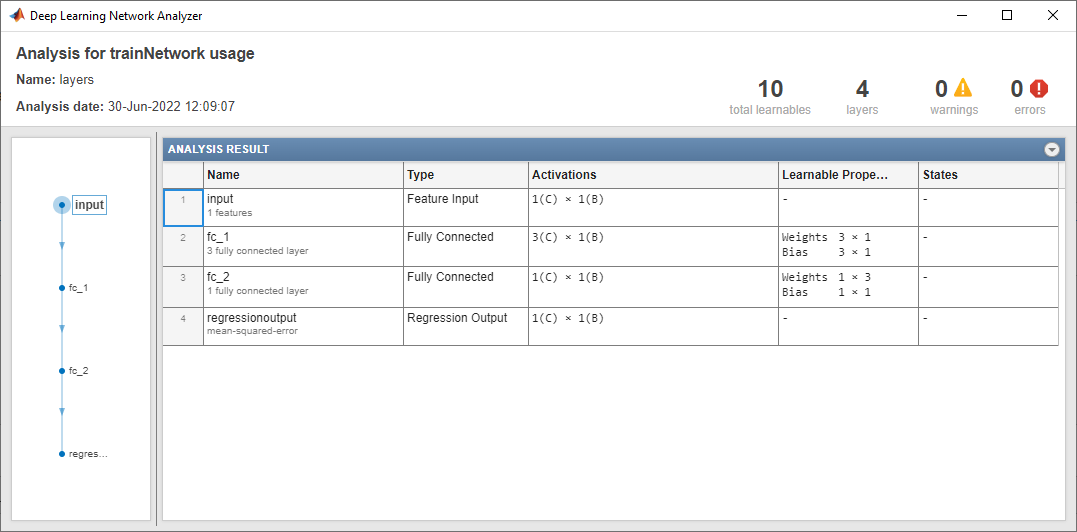

## Specify Training Options and Train Network

Specify the training options.

options = trainingOptions("sgdm", ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.2, ...
    LearnRateDropPeriod=5, ...
    MaxEpochs=5, ...
    MiniBatchSize=10);

Train the network.

trainedNet = trainNetwork(XTrain,TTrain,layers,options);

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         1.68 |          1.4 |          0.0100 |
|       1 |          50 |       00:00:00 |         0.15 |      1.1e-02 |          0.0100 |
|       1 |         100 |       00:00:01 |         0.07 |      2.6e-03 |          0.0100 |
|       1 |         150 |       00:00:01 |         0.07 |      2.1e-03 |          0.0100 |
|       1 |         200 |       00:00:02 |         0.06 |      2.1e-03 |          0.0100 |
|       2 |         250 |       00:00:02 |         0.08 |      3.1e-03 |          0.0100 |
|       2 |         300 |       00:00:02 |         0.03 |      3.9

As this network is small, you can write it explicitly as a function. Let $W_1 ={\left\lbrack w_1 ,w_{2,} w_3 \right\rbrack }^T$, $W_2 =\left\lbrack w_4 ,w_{5,} w_6 \right\rbrack$, $B_1 ={\left\lbrack b_1 ,b_{2,} b_3 \right\rbrack }^T$,  and $B_2 =b_4$, then you can express the network as

$F(x) = W_2(W_1(x) +B_1)+B_2 =  (\omega_1\omega_4 + \omega_2\omega_5 + \omega_3\omega_6)x + (b_1\omega_4 + b_2\omega_5+ b_3\omega_6+b_4)$.

To simplify the problem, set the bias in the first fully connected layer to zero. The network equation now reduces to

$F(x) = (\omega_1\omega_4 + \omega_2\omega_5 + \omega_3\omega_6)x + b_4$.

For the network to exactly describe the underlying function, $f\left(x\right)=x+1$, $\omega_1\omega_4 + \omega_2\omega_5 + \omega_3\omega_6 = 1 $ and $b_4 =1\ldotp$ After rearranging, you can express $\omega_6$ as a combination of the other weights: $\omega_6 = (1-\omega_1\omega_4 - \omega_2\omega_5 )\omega_3^{-1}$, where $\omega_1,  \omega_2,  \omega_3,  \omega_4,  \text{ and } \omega_5 $ are free parameters. 

To confirm that the network is performing well, check if $b_4 =1$ and if $\omega_1\omega_4 + \omega_2\omega_5 + \omega_3\omega_6 = 1 $ where the latter is the dot product of the weights from the first fully connected layer with the weights from the second fully connected layer. 

dot(trainedNet.Layers(2).Weights,trainedNet.Layers(3).Weights) 

ans = single
1.0006

trainedNet.Layers(3).Bias

ans = single
1.0017

Both values are close to 1. This means that the network has learned the correct form of the function.

## Create Equivalent Network

Create a new network that is functionally equivalent but with different values for the learnable parameters. 

As $\omega_1, \omega_2, \omega_3$ can be chosen arbitrarily, make $\omega_1 >> \omega_2$ and move $\omega_3$. Then, rescale $\omega_4,  \omega_5,  \text{ and } \omega_6$ appropriately. This is a network that could minimize the loss if you start training at a different point in learnable parameter space. 

Modify the weights of the fully connected layers with two different scales.

scale = 1e1;

w_fc1 = trainedNet.Layers(2).Weights;
w_fc1(1) = w_fc1(1)*scale;
w_fc1(2) = w_fc1(2)/scale; 
w_fc1(3) = w_fc1(3)*scale; 

w_fc2 = trainedNet.Layers(3).Weights;
w_fc2(1) = w_fc2(1)/scale;
w_fc2(2) = w_fc2(2)*scale;
w_fc2(3) = w_fc2(3)/scale;


Leave the bias values unchanged.

b_fc1 = trainedNet.Layers(2).Bias;
b_fc2 = trainedNet.Layers(3).Bias;

Construct the new network.

layers = [featureInputLayer(numInputs), ...
    fullyConnectedLayer(sizeFC1,Weights=w_fc1,Bias=b_fc1), ...
    fullyConnectedLayer(numOutputs,Weights=w_fc2,Bias=b_fc2), ...
    regressionLayer];

modifiedtrainedNet = assembleNetwork(layers);

## Check Networks are Equivalent

The new weights result in a network that is functionally equivalent to the original network in terms of prediction, architecture, and size. Confirm this by checking that $\omega_1\omega_4 + \omega_2\omega_5 + \omega_3\omega_6 $ is the same for both networks.

dot(trainedNet.Layers(2).Weights,trainedNet.Layers(3).Weights) 

ans = single
1.0006

dot(modifiedtrainedNet.Layers(2).Weights,modifiedtrainedNet.Layers(3).Weights) 

ans = single
1.0006

You can also generate test data and check that the two networks produce the same predictions. 

numTestObservations = 200;
XTest = rand(numTestObservations,1);
TTest = XTest(:,1) + 1 + 0.05*randn(numTestObservations,1);

Plot the predicted values for the test data using the original and modified networks. You can see that the predicted output from both networks is the same.

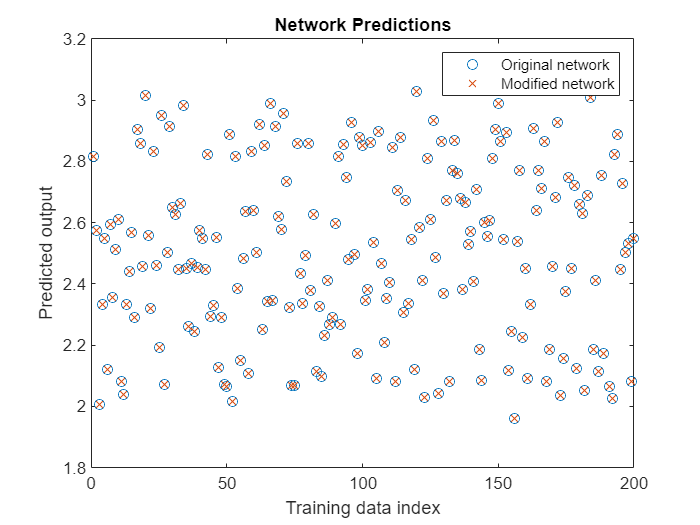

figure
YTestOriginal = predict(trainedNet,TTest);
YTestRescaled = predict(modifiedtrainedNet,TTest);

plot(YTestOriginal,"o");
hold on;
plot(YTestRescaled,"x");
legend("Original network","Modified network")
title("Network Predictions")
ylabel("Predicted output")
xlabel("Training data index")

## Compare Activations

Plot the activations of the networks for the first fully connected layer for the first 10 test observations.

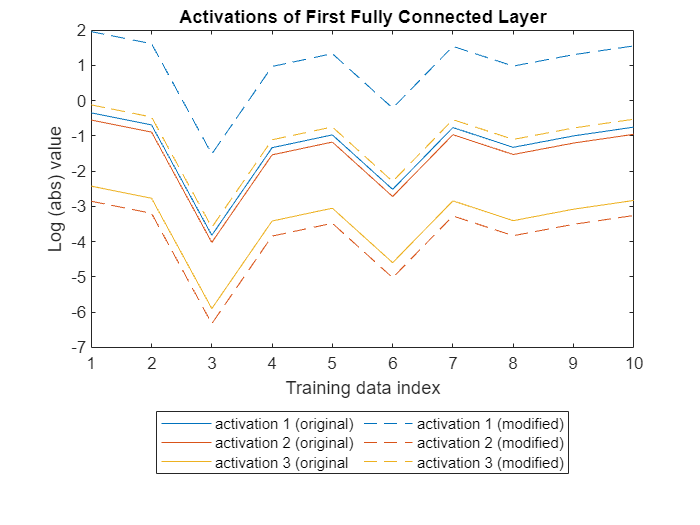

figure

numObservationsToShow = 10;

inputData = XTest(1:numObservationsToShow);
layerIdx = 2;
originalActs = activations(trainedNet,inputData,layerIdx);
modifiedActs = activations(modifiedtrainedNet,inputData,layerIdx);

plot(log(abs(originalActs))');
hold on
set(gca,ColorOrderIndex=1)
plot(log(abs(modifiedActs))',LineStyle="--");
hold off
legend("activation 1 (original)", "activation 2 (original)", "activation 3 (original", ...
    "activation 1 (modified)", "activation 2 (modified)", "activation 3 (modified)", ...
    NumColumns=2, ...
    Location="southoutside");
title("Activations of First Fully Connected Layer")
xlabel("Training data index")
ylabel("Log (abs) value")

Even though the networks are functionally equivalent, the activations are very different for each data point.

To compute the neuron coverage, the activations are rescaled between 0 and 1 for each observation. Rescale the activations.

rescaledOriginalActs = originalActs;
rescaledModifiedActs= modifiedActs;

for i = 1:numObservationsToShow
    rescaledOriginalActs(:,i) = rescale(originalActs(:,i));
    rescaledModifiedActs(:,i) = rescale(modifiedActs(:,i));
end

Plot the rescaled activations.

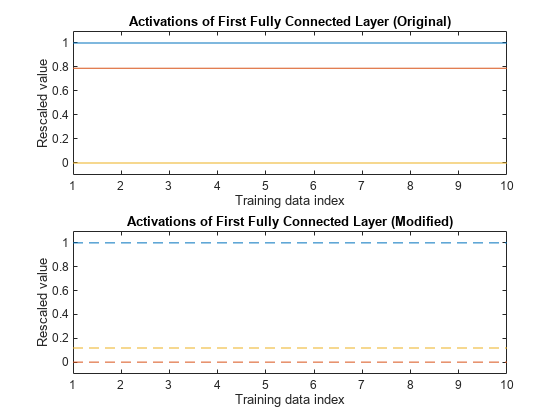

figure
hold on
for i = 1:2
    subplot(2,1,i)
    if i == 1
        plot(rescaledOriginalActs');
        title("Activations of First Fully Connected Layer (Original)")
    else
        plot(rescaledModifiedActs',LineStyle="--");
        title("Activations of First Fully Connected Layer (Modified)")
    end
    hold off
    xlabel("Training data index")
    ylabel("Rescaled value")
    ylim([-0.1,1.1])
end

Both networks have two of the rescaled activations lying at 0 and 1. However, the relative position of the middle activation is very different for the two networks. The neuron coverage threshold corresponds to picking a y-value, and activations that take a value above the threshold, for at least one data point, are considered 'covered'. This is shown explicitly in the following section.

## Neuron Coverage

Compute the neuron coverage for both networks using all of the test data.

To compute the coverage, you must convert the networks to `dlnetwork` objects.

lgraph = layerGraph(trainedNet);
lgraph = removeLayers(lgraph,"regressionoutput");
dlnet = dlnetwork(lgraph);

lgraphModified = layerGraph(modifiedtrainedNet);
lgraphModified = removeLayers(lgraphModified,"regressionoutput");
dlnetModified = dlnetwork(lgraphModified);

Specify a neuron coverage threshold of 0.5 and compute the coverage for both networks.

threshold = 0.5;

nc = neuronCoverage(dlnet,threshold,LayerNames=["fc_1","fc_2"]);
nc = addData(nc,dlarray(XTest',"CB"));

ncModified = neuronCoverage(dlnetModified,threshold,LayerNames=["fc_1","fc_2"]);
ncModified = addData(ncModified,dlarray(XTest',"CB"));

Compare the layer coverage. 

nc.LayerCoverage

ans = 2×1 table
            LayerCoverage
            _____________

    fc_1       0.66667   
    fc_2             0   


ncModified.LayerCoverage

ans = 2×1 table
            LayerCoverage
            _____________

    fc_1       0.33333   
    fc_2             0   


Compare the aggregate coverage. The aggregate coverage of the modified network is lower than the original network even though the prediction capabilities remain the same.

nc.AggregateCoverage

ans = 0.5000

ncModified.AggregateCoverage

ans = 0.2500

## References

Several studies investigate the relationship between coverage and various definitions of robustness for deep learning networks. Many of these studies find little to no evidence that increasing neuron coverage improves network robustness: [1] - [5]. A sample of references are listed here:

[1] Dong, Yizhen, et al. *There Is Limited Correlation between Coverage and Robustness for Deep Neural Networks*. arXiv:1911.05904, arXiv, 13 Nov. 2019. *arXiv.org*, [http://arxiv.org/abs/1911.05904](http://arxiv.org/abs/1911.05904) 

[2] Yan, Shenao, et al. “Correlations between Deep Neural Network Model Coverage Criteria and Model Quality.” *Proceedings of the 28th ACM Joint Meeting on European Software Engineering Conference and Symposium on the Foundations of Software Engineering*, Association for Computing Machinery, 2020, pp. 775–87. *ACM Digital Library*, [https://doi.org/10.1145/3368089.3409671](https://doi.org/10.1145/3368089.3409671)  

[3] Yang, Zhou, et al. *Revisiting Neuron Coverage Metrics and Quality of Deep Neural Networks*. arXiv:2201.00191, arXiv, 1 Jan. 2022. *arXiv.org*, [http://arxiv.org/abs/2201.00191](http://arxiv.org/abs/2201.00191) 

[4] Harel-Canada, Fabrice, et al. “Is Neuron Coverage a Meaningful Measure for Testing Deep Neural Networks?” *Proceedings of the 28th ACM Joint Meeting on European Software Engineering Conference and Symposium on the Foundations of Software Engineering*, Association for Computing Machinery, 2020, pp. 851–62. *ACM Digital Library*, [https://doi.org/10.1145/3368089.3409754](https://doi.org/10.1145/3368089.3409754)  

[5] Pavlitskaya, Svetlana, et al. *Is Neuron Coverage Needed to Make Person Detection More Robust?* arXiv:2204.10027, arXiv, 21 Apr. 2022. *arXiv.org*, [http://arxiv.org/abs/2204.10027](http://arxiv.org/abs/2204.10027) 

*Copyright 2022 The MathWorks, Inc.*